# Set up the Import Options and import the data.

opts = delimitedTextImportOptions("NumVariables", 18);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Country", "Year", "Status", "LifeExpectancy", "AdultMortality", "infantDeaths", "Alcohol", "percentageExpenditure", "HepatitisB", "Measles", "BMI", "underfiveDeaths", "Polio", "TotalExpenditure", "Diphtheria", "HIVAIDS", "GDP", "Schooling"];
opts.VariableTypes = ["categorical", "double", "categorical", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["Country", "Status"], "EmptyFieldRule", "auto");

% Import the data

data = readtable("C:\Users\Gianni\Desktop\functions\Life Expectancy Data.csv", opts)

data = 2938×18 table
      Country      Year      Status      LifeExpectancy    AdultMortality    infantDeaths    Alcohol    percentageExpenditure    HepatitisB    Measles    BMI     underfiveDeaths    Polio    TotalExpenditure    Diphtheria    HIVAIDS     GDP      Schooling
    ___________    ____    __________    ______________    ______________    ____________    _______    _____________________    __________    _______    ____    _______________    _____    

## Clear temporary variables

clear opts

# Separate and visualize the data.

### Life Expectency vs Schooling

% Matrix (2938 x 2) with column 1 = Life Expectency, column 2 = Schooling
school = [data.LifeExpectancy, shift(data.Schooling)]

school =    65.0000   10.1000
   59.9000   10.0000
   59.9000    9.9000
   59.5000    9.8000
   59.2000    9.5000
   58.8000    9.2000
   58.6000    8.9000
   58.1000    8.7000
   57.5000    8.4000
   57.3000    8.1000



% Remove any rows containing NaN from data set
school = byenan(school)

school =    65.0000   10.1000
   59.9000   10.0000
   59.9000    9.9000
   59.5000    9.8000
   59.2000    9.5000
   58.8000    9.2000
   58.6000    8.9000
   58.1000    8.7000
   57.5000    8.4000
   57.3000    8.1000


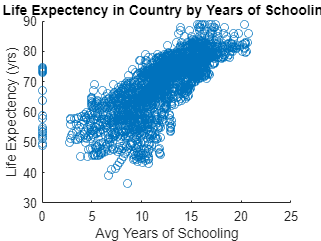

% school now has dimensions (2768 x 2)

% Create scatterplot with Life Expectency on y-axis, 
% Schooling on x-axis
scatter(school(:,2),school(:,1))
title("Life Expectency in Country by Years of Schooling")
xlabel("Avg Years of Schooling")
ylabel("Life Expectency (yrs)")

# Generate Matrix A, and Vector b for each model.

## Create coefficient matrices for "school" matrix

#### Linear Model

[A1,b1] = linfit(school)

A1 =     1.0000   10.1000
    1.0000   10.0000
    1.0000    9.9000
    1.0000    9.8000
    1.0000    9.5000
    1.0000    9.2000
    1.0000    8.9000
    1.0000    8.7000
    1.0000    8.4000
    1.0000    8.1000


b1 =    65.0000
   59.9000
   59.9000
   59.5000
   59.2000
   58.8000
   58.6000
   58.1000
   57.5000
   57.3000


#### Quadratic Model

[A2,b2] = quadfit(school)

A2 =     1.0000   10.1000  102.0100
    1.0000   10.0000  100.0000
    1.0000    9.9000   98.0100
    1.0000    9.8000   96.0400
    1.0000    9.5000   90.2500
    1.0000    9.2000   84.6400
    1.0000    8.9000   79.2100
    1.0000    8.7000   75.6900
    1.0000    8.4000   70.5600
    1.0000    8.1000   65.6100


b2 =    65.0000
   59.9000
   59.9000
   59.5000
   59.2000
   58.8000
   58.6000
   58.1000
   57.5000
   57.3000


#### Cubic Model

[A3,b3] = cubefit(school)

A3 = 	1.0e+03 *

    0.0010    0.0101    0.1020    1.0303
    0.0010    0.0100    0.1000    1.0000
    0.0010    0.0099    0.0980    0.9703
    0.0010    0.0098    0.0960    0.9412
    0.0010    0.0095    0.0902    0.8574
    0.0010    0.0092    0.0846    0.7787
    0.0010    0.0089    0.0792    0.7050
    0.0010    0.0087    0.0757    0.6585
    0.0010    0.0084    0.0706    0.5927
    0.0010    0.0081    0.0656    0.5314


b3 =    65.0000
   59.9000
   59.9000
   59.5000
   59.2000
   58.8000
   58.6000
   58.1000
   57.5000
   57.3000


#### Logarithmic Model

[A4,b4] = logfit(school)

A4 =     1.0000    2.3125
    1.0000    2.3026
    1.0000    2.2925
    1.0000    2.2824
    1.0000    2.2513
    1.0000    2.2192
    1.0000    2.1861
    1.0000    2.1633
    1.0000    2.1282
    1.0000    2.0919


b4 =    65.0000
   59.9000
   59.9000
   59.5000
   59.2000
   58.8000
   58.6000
   58.1000
   57.5000
   57.3000


# Solve Least Squares Problem to Find Curve for Each model Using Various Algorithms.

### Algorithm: Moore-Penrose Psuedoinverse

The minimizer $\vec{x}$ satisfies $A^TA\vec{x} = A^T\vec{b}$, so we will solve for $\vec{x} = (A^TA)^{-1}A^T \vec{b} = A^+\vec{b}$

#### Linear Model: 

x1 = pinv(A1)*b1

x1 =    44.1089
    2.1035



$$f(x) =  44.1089 + 2.1035x$$


#### Quadratic Model: 

x2 = pinv(A2)*b2

x2 =    51.8626
    0.5404
    0.0709



$$f(x) = 51.8626 + 0.5404x + 0.0709x^2$$


#### Cubic Model

x3 = pinv(A3)*b3

x3 =    63.5337
   -4.5636
    0.6413
   -0.0185



$$f(x) = 63.5337 - 4.5636x + 0.6413x^2 - 0.0185x^3$$


#### Logarithmic Model

x4 = pinv(A4)*b4

x4 =    65.7417
    1.5534



$$f(x) = 65.7417 + 1.5534\log(x)$$


## QR Factorization Algorithms:

If $A$ is full rank. We can use QR factorization to solve the least squares problem $A\vec{x} = \vec{b}$.

rank(A1)

ans = 2

rank(A2)

ans = 3

rank(A3)

ans = 4

rank(A4)

ans = 2

$A_i, i = 1,2,3,4$ are all full rank.

Let $A = \hat{Q}\hat{R}$, then $A\vec{x} = \vec{b}$.


$$A^TA\vec{x} =A^T\vec{b}$$



$$(\hat{Q}\hat{R})^T\hat{Q}\hat{R}\vec{x} = (\hat{Q}\hat{R})^T\vec{b}$$



$$\hat{R}^T\hat{Q}^T\hat{Q}\hat{R}\vec{x} = \hat{R}^T\hat{Q}^T\vec{b}$$



$$\hat{R}^T\hat{R}\vec{x} = \hat{R}^T\hat{Q}\vec{b}$$



$$\hat{R}\vec{x} = \hat{Q}^T\vec{b}$$


Since $\hat{R}$ is upper triangular, it will be simple to solve for $\vec{x}$.

### Algorithm: Classical Gram-Schmidt

#### Linear Model:

[Qh_c1,Rh_c1] = cgs(A1) % get reduced QR factorization

Qh_c1 =     0.0190   -0.0108
    0.0190   -0.0114
    0.0190   -0.0119
    0.0190   -0.0125
    0.0190   -0.0142
    0.0190   -0.0159
    0.0190   -0.0176
    0.0190   -0.0187
    0.0190   -0.0204
    0.0190   -0.0222


Rh_c1 =    52.6118  631.3224
         0  176.0304


x_c1 = Rh_c1 \ Qh_c1'*b1 % solve for vector x to write model

x_c1 =    44.1089
    2.1035



norm(A1 - Qh_c1*Rh_c1) % measure accuracy of QR factorization

ans = 1.2578e-14


$$f(x) = 44.1089 + 2.1035x$$


#### Quadratic Model:

[Qh_c2,Rh_c2] = cgs(A2) %get reduced QR factorization

Qh_c2 =     0.0190   -0.0108   -0.0121
    0.0190   -0.0114   -0.0119
    0.0190   -0.0119   -0.0117
    0.0190   -0.0125   -0.0114
    0.0190   -0.0142   -0.0106
    0.0190   -0.0159   -0.0095
    0.0190   -0.0176   -0.0082
    0.0190   -0.0187   -0.0073
    0.0190   -0.0204   -0.0057
    0.0190   -0.0222   -0.0039


Rh_c2 = 	1.0e+03 *

    0.0526    0.6313    8.1646
         0    0.1760    3.8809
         0         0    0.9303


x_c2 = Rh_c2 \ Qh_c2'*b2 % solve for vector x to write model

x_c2 =    51.8626
    0.5404
    0.0709



norm(A2 - Qh_c2*Rh_c2) %measure accuracy of QR factorization

ans = 5.4722e-13


$$f(x) = 51.8626 + 0.5404x + 0.0709x^2$$


#### Cubic Model:

[Qh_c3,Rh_c3] = cgs(A3) %get reduced QR factorization

Qh_c3 =     0.0190   -0.0108   -0.0121    0.0070
    0.0190   -0.0114   -0.0119    0.0077
    0.0190   -0.0119   -0.0117    0.0084
    0.0190   -0.0125   -0.0114    0.0092
    0.0190   -0.0142   -0.0106    0.0114
    0.0190   -0.0159   -0.0095    0.0134
    0.0190   -0.0176   -0.0082    0.0154
    0.0190   -0.0187   -0.0073    0.0167
    0.0190   -0.0204   -0.0057    0.0184
    0.0190   -0.0222   -0.0039    0.0200


Rh_c3 = 	1.0e+05 *

    0.0005    0.0063    0.0816    1.1096
         0    0.0018    0.0388    0.7123
         0         0    0.0093    0.2874
         0         0         0    0.0558


x_c3 = Rh_c3 \ Qh_c3'*b3 % solve for vector x to write model

x_c3 =    63.5337
   -4.5636
    0.6413
   -0.0185



norm(A3 - Qh_c3*Rh_c3) %measure accuracy of QR factorization

ans = 1.2245e-11


$$f(x) = 63.5337 - 4.5636x + 0.6413x^2 - 0.0185x^3$$


#### Logarithmic Model

[Qh_c4,Rh_c4] = cgs(A4) %get reduced QR factorization

Qh_c4 =     0.0190   -0.0001
    0.0190   -0.0003
    0.0190   -0.0004
    0.0190   -0.0006
    0.0190   -0.0010
    0.0190   -0.0014
    0.0190   -0.0019
    0.0190   -0.0022
    0.0190   -0.0027
    0.0190   -0.0032


Rh_c4 =    52.6118  122.1927
         0   72.6280


x_c4 = Rh_c4 \ Qh_c4'*b4 % solve for vector x to write model

x_c4 =    65.7417
    1.5534



norm(A4 - Qh_c4*Rh_c4) %measure accuracy of QR factorization

ans = 9.0876e-15


$$f(x) = 65.7417 + 1.5534\log(x)$$


### Algorithm: Modified Gram-Schmidt

#### Linear Model:

[Qh1,Rh1] = mgs(A1) %get reduced QR factorization

Qh1 =     0.0190   -0.0108
    0.0190   -0.0114
    0.0190   -0.0119
    0.0190   -0.0125
    0.0190   -0.0142
    0.0190   -0.0159
    0.0190   -0.0176
    0.0190   -0.0187
    0.0190   -0.0204
    0.0190   -0.0222


Rh1 =    52.6118  631.3224
         0  176.0304


x_m1 = Rh1 \ Qh1'*b1 % solve for vector x to write model

x_m1 =    44.1089
    2.1035



norm(A1 - Qh1*Rh1) %measure accuracy of QR factorization

ans = 1.2578e-14


$$f(x) = 44.1089 + 2.1035x$$


#### Quadratic Model:

[Qh2,Rh2] = mgs(A2) %get reduced QR factorization

Qh2 =     0.0190   -0.0108   -0.0121
    0.0190   -0.0114   -0.0119
    0.0190   -0.0119   -0.0117
    0.0190   -0.0125   -0.0114
    0.0190   -0.0142   -0.0106
    0.0190   -0.0159   -0.0095
    0.0190   -0.0176   -0.0082
    0.0190   -0.0187   -0.0073
    0.0190   -0.0204   -0.0057
    0.0190   -0.0222   -0.0039


Rh2 = 	1.0e+03 *

    0.0526    0.6313    8.1646
         0    0.1760    3.8809
         0         0    0.9303


x_m2 = Rh2 \ Qh2'*b2 % solve for vector x to write model

x_m2 =    51.8626
    0.5404
    0.0709



norm(A2 - Qh2*Rh2) %measure accuracy of QR factorization

ans = 5.4722e-13


$$f(x) = 51.8626 + 0.5404x + 0.0709x^2$$


#### Cubic Model:

[Qh3,Rh3] = mgs(A3) %get reduced QR factorization

Qh3 =     0.0190   -0.0108   -0.0121    0.0070
    0.0190   -0.0114   -0.0119    0.0077
    0.0190   -0.0119   -0.0117    0.0084
    0.0190   -0.0125   -0.0114    0.0092
    0.0190   -0.0142   -0.0106    0.0114
    0.0190   -0.0159   -0.0095    0.0134
    0.0190   -0.0176   -0.0082    0.0154
    0.0190   -0.0187   -0.0073    0.0167
    0.0190   -0.0204   -0.0057    0.0184
    0.0190   -0.0222   -0.0039    0.0200


Rh3 = 	1.0e+05 *

    0.0005    0.0063    0.0816    1.1096
         0    0.0018    0.0388    0.7123
         0         0    0.0093    0.2874
         0         0         0    0.0558


x_m3 = Rh3 \ Qh3'*b3 % solve for vector x to write model

x_m3 =    63.5337
   -4.5636
    0.6413
   -0.0185



norm(A3 - Qh3*Rh3) %measure accuracy of QR factorization

ans = 1.1647e-11


$$f(x) = 63.5337 - 4.5636x + 0.6413x^2 - 0.0185x^3$$


#### Logarithmic Model

[Qh4,Rh4] = mgs(A4) %get reduced QR factorization

Qh4 =     0.0190   -0.0001
    0.0190   -0.0003
    0.0190   -0.0004
    0.0190   -0.0006
    0.0190   -0.0010
    0.0190   -0.0014
    0.0190   -0.0019
    0.0190   -0.0022
    0.0190   -0.0027
    0.0190   -0.0032


Rh4 =    52.6118  122.1927
         0   72.6280


x_m4 = Rh4 \ Qh4'*b4 % solve for vector x to write model

x_m4 =    65.7417
    1.5534



norm(A4 - Qh4*Rh4) %measure accuracy of QR factorization

ans = 9.0876e-15


$$f(x) = 65.7417 + 1.5534\log(x)$$


### Algorithm: Householder Triangularization (Orthogonal Triangularization)

#### Linear Model:

[Q1,R1,x_h1] = householder(A1,b1) % get QR factorization and vector x

Q1 =    -0.0190   -0.0108   -0.0189   -0.0189   -0.0189   -0.0189   -0.0189   -0.0189   -0.0188   -0.0188   -0.0188   -0.0188   -0.0188   -0.0187   -0.0187   -0.0187   -0.0191   -0.0191   -0.0191   -0.0191   -0.0191   -0.0190   -0.0190   -0.0190   -0.0190   -0.0190   -0.0190   -0.0190   -0.0189   -0.0189   -0.0189   -0.0189   -0.0191   -0.0191   -0.0191   -0.0191   -0.0191   -0.0191   -0.0191   -0.0190   -0.0190   -0.0190   -0.0190   -0.0190   -0.0190   -0.0190   -0.0190   -0.0189   -0.0190   -0.0190
   -0.0190   -0.0114   -0.0121   -0.0126   -0.0144   -0.0161   -0.0178   -0.0189   -0.0206   -0.0223   -0.0234   -0.0297   -0.0314   -0.0331   -0.0348   -0.0371    0.0123    0.0123    0.0123    0.0123    0.0072    0.0027    0.0010   -0.0002   -0.0024   -0.0036   -0.0070   -0.0064   -0.0075   -0.0075   -0.0081   -0.0075    0.0135    0.0135    0.0135    0.0135    0.0112    0.0089    0.0061    0.0033    0.0016    0.0016   -0.0002   -0.0019   -0.0030   -0.0053   -0.0064   -0.0075   -0.0036   -

R1 =   -52.6118 -631.3224
   -0.0000  176.0304
   -0.0000   -0.0000
    0.0000    0.0000
    0.0000    0.0000
   -0.0000   -0.0000
   -0.0000   -0.0000
   -0.0000    0.0000
    0.0000    0.0000
   -0.0000   -0.0000


x_h1 =    44.1089
    2.1035



norm(A1 - Q1*R1) %measure accuracy of QR factorization

ans = 6.8233e-13


$$f(x) = 44.1089 + 2.1035x$$


#### Quadratic Model:

[Q2,R2,x_h2] = householder(A2,b2) % get QR factorization and vector x

Q2 =    -0.0190   -0.0108   -0.0121   -0.0188   -0.0188   -0.0188   -0.0188   -0.0188   -0.0188   -0.0188   -0.0188   -0.0188   -0.0188   -0.0188   -0.0188   -0.0188   -0.0191   -0.0191   -0.0191   -0.0191   -0.0190   -0.0190   -0.0189   -0.0189   -0.0189   -0.0189   -0.0189   -0.0189   -0.0189   -0.0189   -0.0189   -0.0189   -0.0191   -0.0191   -0.0191   -0.0191   -0.0191   -0.0190   -0.0190   -0.0190   -0.0189   -0.0189   -0.0189   -0.0189   -0.0189   -0.0189   -0.0189   -0.0189   -0.0189   -0.0189
   -0.0190   -0.0114   -0.0119   -0.0126   -0.0143   -0.0161   -0.0178   -0.0189   -0.0206   -0.0223   -0.0234   -0.0297   -0.0314   -0.0331   -0.0348   -0.0371    0.0123    0.0123    0.0123    0.0123    0.0072    0.0027    0.0010   -0.0001   -0.0024   -0.0036   -0.0070   -0.0064   -0.0075   -0.0075   -0.0081   -0.0075    0.0135    0.0135    0.0135    0.0135    0.0112    0.0089    0.0061    0.0033    0.0016    0.0016   -0.0001   -0.0019   -0.0030   -0.0053   -0.0064   -0.0075   -0.0036   -

R2 = 	1.0e+03 *

   -0.0526   -0.6313   -8.1646
    0.0000    0.1760    3.8809
   -0.0000   -0.0000    0.9303
    0.0000    0.0000    0.0000
   -0.0000   -0.0000   -0.0000
   -0.0000   -0.0000   -0.0000
   -0.0000   -0.0000   -0.0000
   -0.0000   -0.0000   -0.0000
    0.0000    0.0000   -0.0000
   -0.0000   -0.0000   -0.0000


x_h2 =    51.8626
    0.5404
    0.0709



norm(A2 - Q2*R2) %measure accuracy of QR factorization

ans = 1.0780e-11


$$f(x) = 51.8626 + 0.5404x + 0.0709x^2$$


#### Cubic Model:

[Q3,R3,x_h3] = householder(A3,b3) % get QR factorization and vector x

Q3 =    -0.0190   -0.0108   -0.0121   -0.0070   -0.0187   -0.0187   -0.0186   -0.0186   -0.0186   -0.0186   -0.0186   -0.0185   -0.0185   -0.0185   -0.0186   -0.0186   -0.0192   -0.0192   -0.0192   -0.0192   -0.0192   -0.0191   -0.0190   -0.0190   -0.0190   -0.0189   -0.0189   -0.0189   -0.0188   -0.0188   -0.0188   -0.0188   -0.0193   -0.0193   -0.0193   -0.0193   -0.0192   -0.0192   -0.0191   -0.0191   -0.0190   -0.0190   -0.0190   -0.0190   -0.0189   -0.0189   -0.0189   -0.0188   -0.0189   -0.0189
   -0.0190   -0.0114   -0.0119   -0.0077   -0.0143   -0.0160   -0.0177   -0.0188   -0.0205   -0.0222   -0.0233   -0.0296   -0.0313   -0.0330   -0.0347   -0.0370    0.0123    0.0123    0.0123    0.0123    0.0072    0.0026    0.0009   -0.0002   -0.0024   -0.0036   -0.0070   -0.0064   -0.0075   -0.0075   -0.0081   -0.0075    0.0134    0.0134    0.0134    0.0134    0.0111    0.0089    0.0060    0.0032    0.0015    0.0015   -0.0002   -0.0019   -0.0030   -0.0053   -0.0064   -0.0075   -0.0036   -

R3 = 	1.0e+05 *

   -0.0005   -0.0063   -0.0816   -1.1096
   -0.0000    0.0018    0.0388    0.7123
   -0.0000    0.0000    0.0093    0.2874
    0.0000   -0.0000   -0.0000   -0.0558
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000   -0.0000    0.0000
    0.0000    0.0000   -0.0000    0.0000
   -0.0000    0.0000   -0.0000    0.0000
   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0000   -0.0000    0.0000    0.0000


x_h3 =    63.5337
   -4.5636
    0.6413
   -0.0185



norm(A3 - Q3*R3) %measure accuracy of QR factorization

ans = 2.0985e-10


$$f(x) = 63.5337 - 4.5636x + 0.6413x^2 - 0.0185x^3$$


#### Logarithmic Model

[Q4,R4,x_h4] = householder(A4,b4) % get QR factorization and vector x

Q4 =    -0.0190   -0.0001   -0.0190   -0.0190   -0.0190   -0.0190   -0.0190   -0.0190   -0.0190   -0.0189   -0.0189   -0.0189   -0.0189   -0.0189   -0.0189   -0.0188   -0.0191   -0.0191   -0.0191   -0.0191   -0.0191   -0.0191   -0.0191   -0.0190   -0.0190   -0.0190   -0.0190   -0.0190   -0.0190   -0.0190   -0.0190   -0.0190   -0.0191   -0.0191   -0.0191   -0.0191   -0.0191   -0.0191   -0.0191   -0.0191   -0.0191   -0.0191   -0.0190   -0.0190   -0.0190   -0.0190   -0.0190   -0.0190   -0.0190   -0.0190
   -0.0190   -0.0003   -0.0008   -0.0009   -0.0013   -0.0018   -0.0022   -0.0025   -0.0030   -0.0035   -0.0039   -0.0059   -0.0066   -0.0072   -0.0079   -0.0089    0.0042    0.0042    0.0042    0.0042    0.0033    0.0024    0.0021    0.0019    0.0014    0.0012    0.0004    0.0006    0.0003    0.0003    0.0002    0.0003    0.0044    0.0044    0.0044    0.0044    0.0040    0.0036    0.0031    0.0026    0.0022    0.0022    0.0019    0.0015    0.0013    0.0008    0.0006    0.0003    0.0012    

R4 =   -52.6118 -122.1927
    0.0000   72.6280
    0.0000    0.0000
   -0.0000   -0.0000
   -0.0000    0.0000
   -0.0000    0.0000
   -0.0000    0.0000
   -0.0000   -0.0000
   -0.0000   -0.0000
    0.0000   -0.0000


x_h4 =    65.7417
    1.5534



norm(A4 - Q4*R4) %measure accuracy of QR factorization

ans = 1.9081e-13


$$f(x) = 65.7417 + 1.5534\log(x)$$


### Algorithm: Singular Value Decomposition

#### Linear Model:

x_s1 = svdSolver(A1,b1)

x_s1 = 2×1
   44.1089
    2.1035



$$f(x) = 44.1089 + 2.1035x$$


#### Quadratic Model:

x_s2 = svdSolver(A2,b2)

x_s2 = 3×1
   51.8626
    0.5404
    0.0709



$$f(x) = 51.8626 + 0.5404x + 0.0709x^2$$


#### Cubic Model:

x_s3 = svdSolver(A3,b3)

x_s3 = 4×1
   63.5337
   -4.5636
    0.6413
   -0.0185



$$f(x) = 63.5337 - 4.5636x + 0.6413x^2 - 0.0185x^3$$


#### Logarithmic Model

x_s4 = svdSolver(A4,b4)

x_s4 = 2×1
   65.7417
    1.5534



$$f(x) = 65.7417 + 1.5534\log(x)$$


# Measure Fit for Each Model. Determine Best Fitting Model.

All five algorithms applied to the data led to the same coefficients for each model. We can now measure which model fits best by seeing which model minimizes the 2-norm of the residuals vector $\vec{r}$.

 
$$||\vec{r}|| = ||\vec{b} - A\vec{x}||$$


% Measure linear model
measurefit(b1,A1,x1)

ans = 324.5848


% Measure quadratic model
measurefit(b2,A2,x2)

ans = 317.8129


% Measure cubic model
measurefit(b3,A3,x3)

ans = 300.6294


% Measure logarithmic model
measurefit(b4,A4,x4)

ans = 479.2990

The cubic model minimizes $||\vec{r}||$, thus the best fit out of the 4 candidate models is:

#### 
$$f(x) = 63.5337 - 4.5636x + 0.6413x^2 - 0.0185x^3$$


% define function
f = @(x) 63.5337 - 4.5636*x + 0.6413*x.^2 - 0.0185*x.^3

f = function_handle with value:
    @(x)63.5337-4.5636*x+0.6413*x.^2-0.0185*x.^3



% define range for plot of function
x = 0:1:23

x = 1×24
     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23


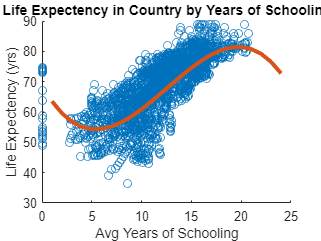

% scatterplot
scatter(school(:,2),school(:,1))
title("Life Expectency in Country by Years of Schooling")
xlabel("Avg Years of Schooling")
ylabel("Life Expectency (yrs)")

% add to above scatterplot
hold on 

% plot curve for cubic model
plot(f(x),'color','#D95319',"LineWidth",3)

% stop adding to above sacatterplot
hold off

# Condition Number and Noise

% setting seed
rng(0)

% Checking condition number of each model 
cond(A1) %Linear

ans = 46.6593

cond(A2) %Quadratic 

ans = 1.2678e+03

cond(A3) %Cubic

ans = 2.5012e+04

cond(A4) %Log

ans = 5.8412


%%% Looking at our condition numbers, we are interested in checking our
%%% quadratic model and cubic model in how we can improve fit by adding
%%% noise 

%_p = prime

%%% Checking quadratic
b2_p = noiseGenerator(b2, 0.1) % adding 10% noise to b2

b2_p =    72.2510
   67.9615
   61.0302
   67.6290
   64.8280
   59.6681
   61.0786
   62.9672
   66.0218
   65.8875



%%% Checking using the Moore-Penrose psuedoinverse
x2_p = pinv(A2)*b2_p

x2_p =    56.1542
    0.5738
    0.0695


x2_pSVD = svdSolver(A2, b2_p)

x2_pSVD =    56.1542
    0.5738
    0.0695


%%% Now we check for residual
% MP
measurefit(b2_p, A2, x2_p)

ans = 343.5766

% SVD
measurefit(b2_p, A2, x2_pSVD)

ans = 343.5766

%%% Conclusion for quadratic, noise improves model 


%%% Checking cubic
b3_p = noiseGenerator(b3, 0.1) % adding 10% noise to b3

b3_p =    65.6082
   63.5474
   60.9981
   63.4428
   67.2006
   61.9474
   59.6696
   63.1651
   65.2878
   60.4023



%%% Checking using the Moore-Penrose psuedoinverse
x3_p = pinv(A3)*b3_p

x3_p =    68.7164
   -4.7136
    0.6519
   -0.0187


%%% Now we check for residual
measurefit(b3_p, A3, x3_p)

ans = 328.6243


%%% Conclusion for cubic, noise improves model 

% Creating an improved model with noise for cubic

% define function
f2 = @(x2) 68.7164 - 4.7136*x + 0.6519*x.^2 - 0.0187*x.^3

f2 = function_handle with value:
    @(x2)68.7164-4.7136*x+0.6519*x.^2-0.0187*x.^3



% define range for plot of function
x2 = 0:1:23

x2 =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23


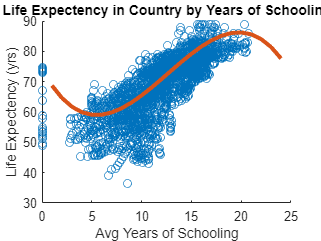


% scatterplot
scatter(school(:,2),school(:,1))
title("Life Expectency in Country by Years of Schooling")
xlabel("Avg Years of Schooling")
ylabel("Life Expectency (yrs)")

% add to above scatterplot
hold on 

% plot curve for cubic model
plot(f2(x2),'color','#D95319',"LineWidth",3)

% stop adding to above sacatterplot
hold off